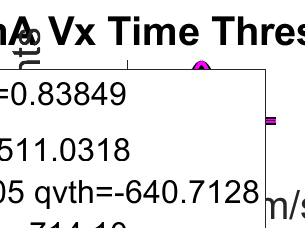

N_TIME_STEPS = 1428;
trackV = ma.getVelocities; % Retrieve instantaneous velocities, per track
t_min = 14.00;
t_max = 17.00;
Total_particles =  numel(trackV);
lim_trackV=[];

for i=1:Total_particles
    particle = trackV{i,1};
    if particle(1,1) < t_max && particle(1,1) >= t_min
        lim_trackV{i,1} = trackV{i,1};
    end
end

TV = vertcat( lim_trackV{:} );
V = TV(:, 2:3);

[Nx,Xx] = hist(V(:,1),(N_TIME_STEPS/2)); 
[Ny,Xy] = hist(V(:,2),(N_TIME_STEPS/2)); 


% Maxwellian distribution
modelFun = @(p,x) (1./(sqrt(2*pi)*p(2))).*p(1).*exp(-0.5*(((x-p(3)))./p(2)).^2); % Gaussian

% Fit for Vx
M_Vxstart = [7000,700,0]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
M_Vx = nlinfit(Xx,Nx,modelFun,M_Vxstart);
M_Vx_eval = modelFun(real(M_Vx),Xx);

% Fit for Vy
M_Vystart = [12000,200,300]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
M_Vy = nlinfit(Xy,Ny,modelFun,M_Vystart);
M_Vy_eval = modelFun(real(M_Vy),Xy);

%q-Gaussian
modelFun = @(p,x)  abs(p(1)).*(1./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^(2))))).^(1/(p(4)-1))));
% Fit for Vx
Q_Vxstart = [200,0,1,1.2];
Q_Vx = nlinfit(Xx,Nx,modelFun,Q_Vxstart);
Q_Vx_eval = modelFun(real(Q_Vx),Xx);

% Fit for Vy
Q_Vystart = [11000,4,600,1.8];
Q_Vy = nlinfit(Xy,Ny,modelFun,Q_Vystart);
Q_Vy_eval = modelFun(real(Q_Vy),Xy);

%super and super without normalization 
modelFun = @(p,x) (abs(p(1))./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^2)))).^(1/(p(4)-1)))) + (abs(p(1))./((1+((((x-p(5))).^2)./(((p(7)-1)^(-1)).*(abs(p(6)).^2)))).^(1/(p(7)-1))));  
% Fit for Vy
Qsb_Vystart = [300,0,300,1.4,0,300,1.4];
Qsb_Vy = nlinfit(Xy,Ny,modelFun,Qsb_Vystart);
Qsb_Vy_eval = modelFun(real(Qsb_Vy),Xy);

SPACE_UNITS = 'um';
TIME_UNITS = 's';

figure
bar(Xx,Nx)
box off
hold on
plot(Xx,M_Vx_eval,'k','LineWidth',4); % Fit Gaussian distribution to the histogram
plot(Xx,Q_Vx_eval,'m','Linewidth',2); %Fit Q Gaussian (Best fit)
title('70Pa 0.7mA Vx Time Threshold 0-5 Cam1') % Change the title to reflect the parameters of the dataset used
xlabel([ 'Velocity (' SPACE_UNITS '/' TIME_UNITS ')' ])
ylabel('Counts')
xlim([-3000 3000])
set(gca,'FontSize',18); % Set axis fornsize to 18
plot(0,0,'w'); %this is to create extra legend space
legend({['v_{x} v_x_0=' num2str(Q_Vx(2))], ['Mvth=' num2str(M_Vx(2))], ['q=' num2str(Q_Vx(4)) ' qvth=' num2str(Q_Vx(3))],['Counts ' num2str(Q_Vx(1),'%.2f')]}, 'Location', 'northeast');

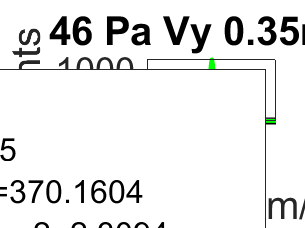


%y-componenet velocities
figure
bar(Xy,Ny)
box on
hold on
plot(Xy,M_Vy_eval,'k','LineWidth',3.5); % 
plot(Xy,Q_Vy_eval,'m','LineWidth',2);
plot(Xy,Qsb_Vy_eval,'g','LineWidth',2); % 
plot(0,0,'w'); %this is to create extra legend space
plot(0,1,'w'); 
xlabel([ 'Velocity (' SPACE_UNITS '/' TIME_UNITS ')' ])
ylabel('Counts')
xlim([-3000 3000])
set(gca,'FontSize',18); % Set axis fornsize to 18
title('46 Pa Vy 0.35mA ') % Change the title to reflect the parameters of the dataset used
legend({['v_{y} v_y_0=' num2str(Q_Vy(2))], ['M vth=' num2str(M_Vy(2))], ['q=' num2str(Q_Vy(4)) ' qvth=' num2str(Q_Vy(3))],['qsp1=' num2str(real(Qsb_Vy(4))) ' qsp2=' num2str(real(Qsb_Vy(7)))],['qvth1=' num2str(real(Qsb_Vy(3))) ' qvth2=' num2str(real(Qsb_Vy(6)))],['qsp Counts ' num2str(real(Qsb_Vy(1)),'%.2f')]}, 'Location', 'northeast','AutoUpdate','on');